# Kellogg Problem

close all; clear variables;

## Problem setting


$$-\nabla\cdot(d\nabla u) = 0  \quad \Omega = (-1,1)\times (-1,1)$$



$$u = g_D \quad \partial \Omega$$


The diffusion constant is discontinous; see the figure below. We set a2 = 1; a1 = 161.4476387975881 and choose boundary condition $g_D$ such that the exact solution is $z = r^{0.1}\mu(\theta)$ in the poloar coordinate, where the formula of $\mu$ can be found in exactu function.

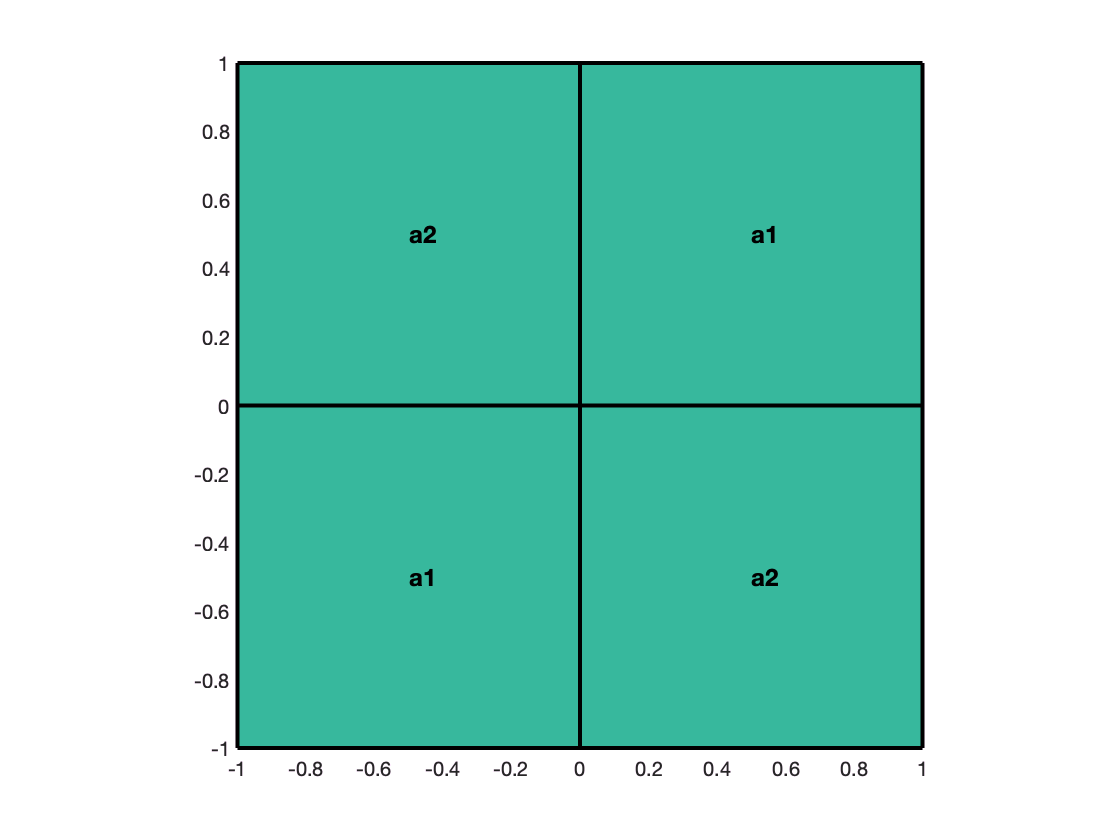

[x,y] = meshgrid(-1:1:1,-1:1:1); 
z = 0*x;
surf(x,y,z,'linewidth',2); view(2);
axis equal; axis tight;
text(0.5,0.5,'a1','FontSize',12,'FontWeight','bold');
text(-0.5,-0.5,'a1','FontSize',12,'FontWeight','bold');
text(-0.5,0.5,'a2','FontSize',12,'FontWeight','bold');
text(0.5,-0.5,'a2','FontSize',12,'FontWeight','bold');

## Parameters

maxN = 1e3;     theta = 0.1;    maxIt = 1000; 
N = zeros(maxIt,1);     
uIuhErr = zeros(maxIt,1);
errH1 = zeros(maxIt,1);

## Generate an initial mesh

[node,elem] = squaremesh([-1 1 -1 1], 0.25);
bdFlag = setboundary(node,elem,'Dirichlet');

## Set up PDE data

pde = Kelloggdata;

## Adaptive Finite Element Method

**SOLVE** -> **ESTIMATE** -> **MARK** -> **REFINE/COARSEN**

Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     2009,  #nnz:    11809, smoothing: (1,1), iter:  8,   err = 3.25e-09,   time = 0.29 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     2127,  #nnz:    12471, smoothing: (1,1), iter:  8,   err = 3.70e-09,   time = 0.29 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     2229,  #nnz:    13053, smoothing: (1,1), iter:  8,   err = 2.42e-09,   time = 0.25 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     2351,  #nnz:    13735, smoothing: (1,1), iter:  8,   err = 2.45e-09,   time = 0.27 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     2465,  #nnz:    14393, smoothing: (1,1), iter:  8,   err = 2.47e-09,   time = 0.26 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     2611,  #nnz:    15183, smoothing: (1,1), iter:  8,   err = 3.09e-09,   time = 0.33 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     2731,  #nnz:    15859, smoothing: (1,1), iter:  8,   err = 2.88e-09,   time = 0.27 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     2903,  #nnz:    16779, smoothing: (1,1), iter:  8,   err = 3.21e-09,   time = 0.27 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     3063,  #nnz:    17647, smoothing: (1,1), iter:  8,   err = 2.86e-09,   time = 0.32 s


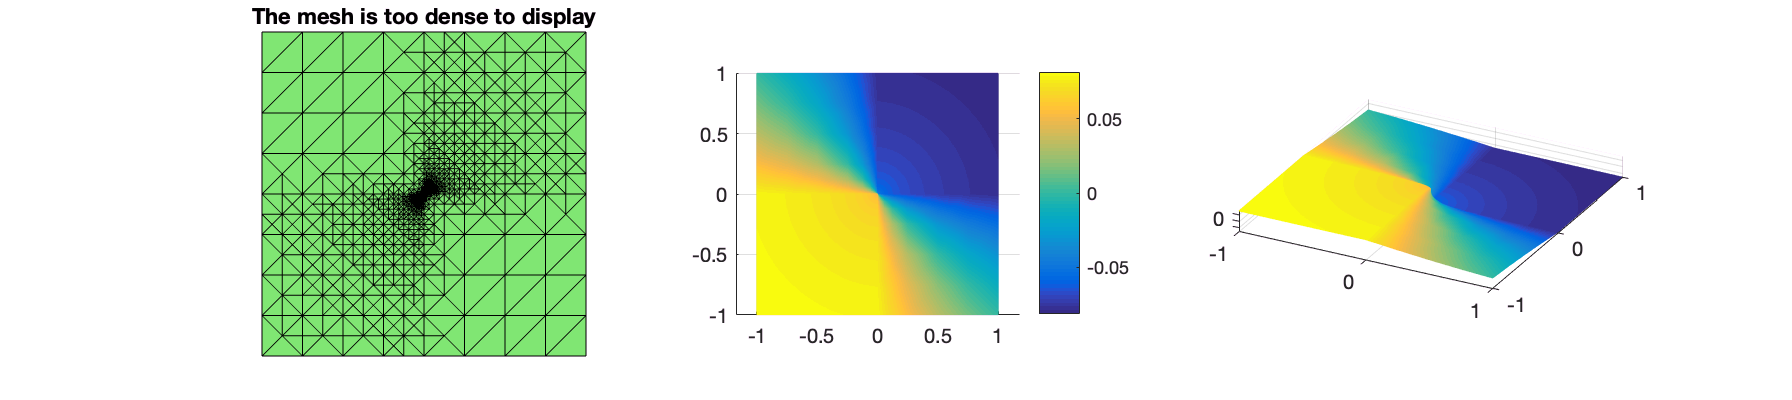

for k = 1:maxIt
    % Step 1: SOLVE
    [soln,eqn,info] = Poisson(node,elem,bdFlag,pde);
    % Plot mesh and solution
    figure(1);  showresult(node,elem,soln.u,[27,26]);    
    % Step 2: ESTIMATE
%    eta = estimaterecovery(node,elem,u);            % recovery type
    eta = estimateresidual(node,elem,soln.u,pde);    % residual type
    % Record error and number of vertices
    uI = pde.exactu(node);
    uIuhErr(k) = sqrt((uI-soln.u)'*eqn.A*(uI-soln.u));
    errH1(k) = getH1error(node,elem,@pde.Du,soln.Du,5);
    N(k) = size(node,1);
    if (N(k)>maxN), break; end        
    % Step 3: MARK
    markedElem = mark(elem,eta,theta);
    % Step 4: REFINE
    [node,elem,bdFlag,HB,tree] = bisect(node,elem,markedElem,bdFlag);
    % COARSEN
    eta = eleminterpolate(eta,tree);
    markedElem = mark(elem,eta,0.5*theta,'COARSEN');
    [node,elem,bdFlag] = coarsen(node,elem,markedElem,bdFlag);
end

## Plot convergent rates in energy norm

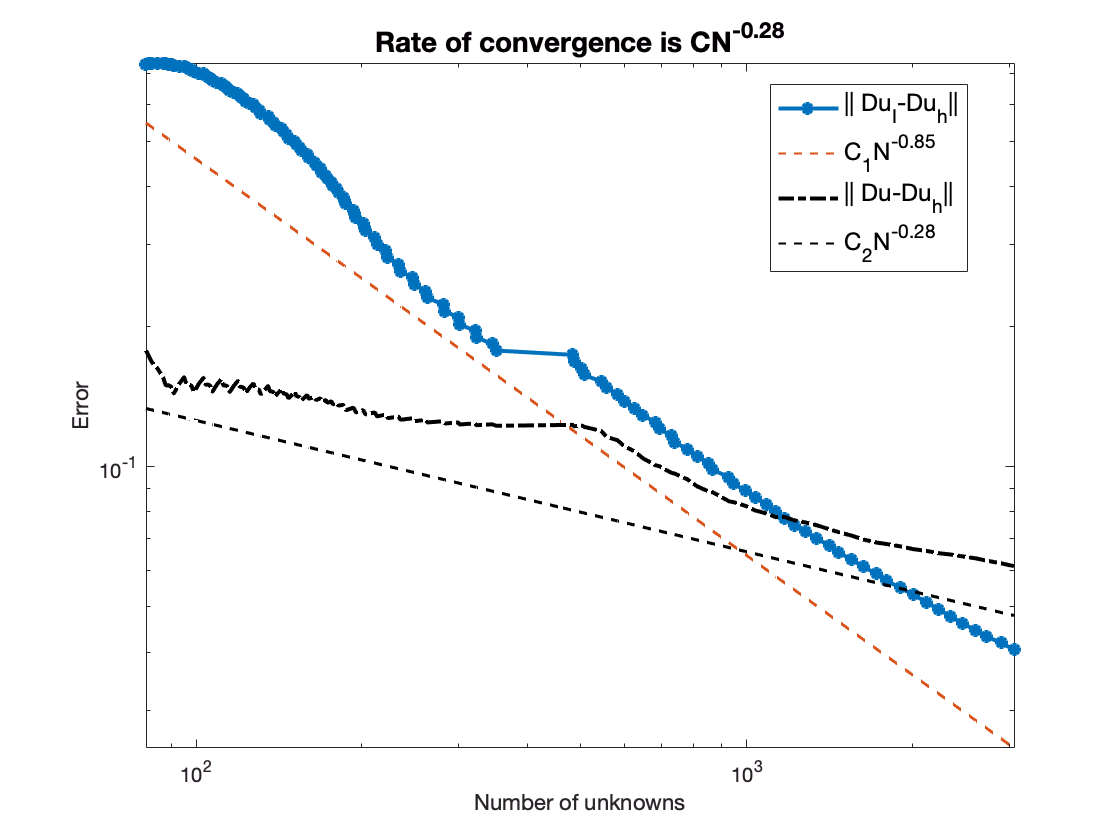

figure(2)
showrate2(N(1:k),uIuhErr(1:k),30,'-*','|| Du_I-Du_h||',...
          N(1:k),errH1(1:k),30,'k-.','|| Du-Du_h||');